# Principal Moments of Inertia

## What we're going to do:

In this FAQ, we're going to explore the principal moments of inertia of a rigid body.  Key topics that we'll look at are:

- review Eigenvalues for a general matrix

- review Eigenvalues for a **SYMMETRIC** matrix

- review passive rotations and the DCM

After reviewing these topics we'll present the solution to determining the **PRINCIPAL** moments of inertia.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Eigenvalue problems

Recall the eigenvalue problem for a square matrix $A \in R^{n \times n}$:


$$A  \times \vec{v} _i = \lambda_i . \vec{v}_i 
$$
  
$$\Longrightarrow$$
  
$$det( A - \lambda_i *  I) = 0$$


After determining ALL of the eignvalue ($\lambda_j$) and eigenvector ($\vec{v_j}$) pairs , we can collect them into matrices and write them as a single matrix equation:


$$A \times V =  V \times \Lambda$$
  

where

 
$$V = \pmatrix{ \vec{v}_1 \enspace, \vec{v}_1 \enspace , \vec{v}_3 \enspace , \enspace \ldots \enspace , \vec{v}_n }$$



$$\Lambda = \pmatrix{ 
\lambda_1 & 0  & 0 & 0 \ldots \cr 
0 & \lambda_2 & 0 & 0  \ldots  \cr
0 & 0 & \ddots & 0  \ldots  \cr
0 & 0 & \ldots &  \lambda_n 
}$$


So you can see that we can covert A into a diaginal matrix using the matrix of A's eigenvectors:


$$A \times V = V \times \Lambda  $$



$$ \Lambda = V^{-1} \times A \times V$$


Let's have a look at an example using MATLAB's `eig()` function:

% a test matrix
A = [ 1, 2, 3;
      4, 0, 6;
      7, 8, 9];
% compute the eignvectors and eigenvalues  

V =     0.2496    0.8346    0.0334
    0.4198   -0.0387   -0.8553
    0.8726   -0.5495    0.5170


lambda =    14.8509         0         0
         0   -1.0680         0
         0         0   -3.7829


[V, lambda] = eig(A)  
% look at how we can diagonalise A:

Ad =    14.8509    0.0000         0
    0.0000   -1.0680   -0.0000
   -0.0000    0.0000   -3.7829


Ad = inv(V) * A * V


zz =      1     2     3     4


## Eigenvalue problems:  When A is Symmetric 

When A is symmetric, ie: $A = A^T$, the eigenvectors corresponding to the distinct eigenvalues have a cool property - the eigenvectors are actually ORTHOGONAL, ie:

                                $\vec{v_j}^T \times \vec{v_k} = 0 $,          for $j \neq k$  and

                                $\vec{v_j}^T \times \vec{v_j} = {| \vec{v_j}} |^2 $,    for $j = k$

If we normalise each of these eigenvectors so that their vector norm is 1 (ie: $\vec{v_j}^T \times \vec{v_j} = 1$), then we say that the eigenvectors are ORTHONORMAL, ie:


$$V \times V^T = I$$



$$V^T = V^{-1}$$


Therefore our diagonalization formula introduced earlier, can now be written as:


$$A \times V = V \times \Lambda  $$



$$ \Lambda = V^{-1} \times A \times V$$



$$ \Lambda = V^{T} \times A \times V$$


So ?  - So in the case of symmetric matrices, not only can the eigenvectors be used to diagonalise A, but you can think of the ORTHONORMAL eigenvector matrix as being a **PASSIVE** rotation matrix, ie:


$$ V^T =  {^PR_B}  \qquad \Longrightarrow \qquad V = {^BR_P}$$


**ATTENTION**:

*One small detail that we need to mention is that in order to interpret *$[V]$* as a rotation matrix, we need to ensure that the 3 basis vectors in *$[V]$* form a right handed co-ordinate frame, ie: just because 3 unit vectors are mutually orthogonal doesn't mean they form a RH frame (eg: *$[\vec{i}, \quad \vec{j},\quad -\vec{k}]$*). So an easy way to ensure we have a RH rule frame is to redefine *$[V]$* as:*


$$V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$$


Let's look at an example:  

*(NOTE:  the eigenvectors returned by MATLAB's eig() are actually normaised to unity .... but I'll demonstrate the normalisation process anyway)*

% here is a symmetric matrix A
A = [  1,   -9,  -17;
      -9,    2,   45;
     -17,   45,    3; ];
 
% compute the eignvectors and eigenvalues   
[V, lambda] = eig(A) 

V =     0.1357    0.9341   -0.3302
   -0.6848    0.3293    0.6501
    0.7160    0.1379    0.6844


lambda =   -43.2641         0         0
         0   -4.6830         0
         0         0   53.9471


% get the magnitude of each eignvector
row_of_eVec_mags = sqrt( sum(V.^2) )

row_of_eVec_mags =     1.0000    1.0000    1.0000


% normalise the eigenvectors by their magnitudes
% NOTE: BSXFUN expands the ROW vector to create a matrix of the same size as V
%       so after the replication of the ROW, BSXFUN simply does a  (V_mat ./ R_mat) 
V = bsxfun(@rdivide, V, row_of_eVec_mags)

V =     0.1357    0.9341   -0.3302
   -0.6848    0.3293    0.6501
    0.7160    0.1379    0.6844


% demonstrate that V is made up of orthonormal vectors
B = V * V.'

B =     1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


OK, so we have 3 mutually orthogonal vectors ... which is awesome, but do these 3 vectors form a Right hand rule trio of vectors?  We can ensure that they do by making the 3rd vector the cross product of the first two, eg:  $V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$

tmp_3 = cross(V(:,1), V(:,2) );
% CHECK RH co-ordinate frame - part 1
tmp_diff = tmp_3 - V(:,3);
tmp_mag  = norm(tmp_diff);
if( tmp_mag < 1e-7 )
    % everything is fine ... move along
else
    warning('HEY!: I am modifying V, so I have a RH frame');
    V(:,3) = tmp_3;
end

% CHECK RH co-ordinate frame - part 2
VT = V';
tmp_3 = cross(VT(:,1), VT(:,2) );
tmp_diff = tmp_3 - VT(:,3);
tmp_mag  = norm(tmp_diff);
if( tmp_mag > 1e-7 )
    error('HEY!: I do not think you have a RH co-ordinate frame ?');
end

## Principal moments of Inertia:

OK, now for the main event.  Let's look at how we now calculate the principal axes of a rigid body.  Recall our well known angular momentum equation where the axis about which we are determining the angular momentum is both BODY fixed AND at the body's centre of mass:

        $\pmatrix{L_{X} \cr L_{\thinspace Y} \cr L_{\thinspace  Z}} = 
\pmatrix{
I_{XX} & I_{XY} & I_{XZ} \cr
I_{XY} & I_{YY} & I_{YZ} \cr
I_{XZ} & I_{YZ} & I_{ZZ} \cr
} \times
\pmatrix{^B_G\omega_X \cr 
^B_G\omega_Y \cr 
^B_G\omega_Z \cr 
}$      where      $\matrix{ I_{ZZ} = \int (X^2 + Y^2) \thinspace dm \cr
I_{XY} = \int(-X *Y) \thinspace dm \cr
}$       etc.

ie:            $^BL = {^BI} \times {^B\omega}$

What we would like to do is to determine a new co-ordinate frame called the **PRINCIPAL** frame, where the Inertia matrix is diagonal, ie:


$$^PL = {^PI} \times {^P\omega} \qquad where \qquad {^PI} = \pmatrix{
I_1 & 0 & 0 \cr
0 & I_2 & 0 \cr
0 & 0 & I_3 \cr
} $$


To determine this new **PRINCIPAL** frame we need to find a co-ordinate transformation $^PR_B$ that converts co-ordinates in the original body *"B-frame"* into their corresponding co-ordinates in the new **PRINCIPAL** *"P-frame".   *If this looks/sounds familiar, it should .... because what we've described is just a PASSIVE rotation, ie: we have a FIXED *B-frame*, and we will rotate a *P-frame* relative to B. And $^PR_B$ is just the PASSIVE rotation matrix, ie:  ${^Pu} = {^PR_B} \times {^Bu}$.  Consider then the following:


$${^P\omega} = {^PR_B} \times {^B\omega} \qquad \Longrightarrow \qquad {^B\omega} = {^PR_B^T} \times {^P\omega}$$



$${^PL} = {^PR_B} \times {^BL} \qquad \Longrightarrow \qquad {^BL} = {^PR_B^T} \times {^PL}$$


Now let's focus on the angular momentum described in the B-frame


$$^BL = {^BI} \times {^B\omega}$$



$$({^PR_B^T} \times {^PL}) = {^BI} \times  ({^PR_B^T} \times {^P\omega})$$



$$^PL = ({^PR_B \times {^BI} \times {^PR_B^T}) \times {^P\omega}$$



$$^PL = {^PI} \times {^P\omega}   \qquad where \qquad {^PI} = ({^PR_B \times {^BI} \times {^PR_B^T}) $$
   

The equation for $^PI$ has the form ($^PI = H\times {^BI} \times H^T$) which is similar in shape to what we saw when we discussed eigenvectors of symmetric matrices. As disussed in the previous section on eigenvectors of SYMMETRIC matrices, the rotation matrix $^PR_B$ we are looking for is simply the normalised eigenvector matrix of ${^BI}$. So here's what we need to do:


$${^BI}  \times \vec{v} _i = \lambda_i . \vec{v}_i $$



$${^BI} \times V =  V \times \Lambda \qquad \Longrightarrow \qquad \Lambda = V^{-1} \times {^BI} \times V = {^PI}$$


So ? - So we've finally converged on some useful results:

- The **PRINCIPAL** moments of inertia are the eigenvalues of ${^BI}$

- The orientation of the **PRINCIPAL** axes is defined by the matrix of normalised eigenvectors $V$

- Where $V$is actually the inverse of the rotation matrix: ${V^{-1}} \equiv {^PR_B} \qquad \Longrightarrow \qquad {V} = {^PR_B^{-1}} =  {^PR_B^T}$

**RECALL the one small detail:**

*One small detail that we need to mention is that in order to interpret *$[V]$* as a rotation matrix, we need to ensure that the 3 basis vectors in *$[V]$* form a right handed co-ordinate frame, ie: just because 3 unit vectors are mutually orthogonal doesn't mean they form a RH frame. So an easy way to do this is to redefine *$[V]$* as:*


$$V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$$


Let's explore:

syms I_xx I_xy I_xz I_yy I_yz I_zz lambda
% define the originl inerti matrix
bI = [I_xx, I_xy, I_xz;
      I_xy, I_yy, I_yz;
      I_xz, I_yz, I_zz ]
% create the eigenvalue problem

$$bI = \left(\begin{array}{ccc} I_{\mathrm{xx}} & I_{\mathrm{xy}} & I_{\mathrm{xz}}\\ I_{\mathrm{xy}} & I_{\mathrm{yy}} & I_{\mathrm{yz}}\\ I_{\mathrm{xz}} & I_{\mathrm{yz}} & I_{\mathrm{zz}} \end{array}\right)$$

e_mat = bI - lambda*eye(3)
det_e = det(e_mat);

$$e\_mat = \left(\begin{array}{ccc} I_{\mathrm{xx}}-\lambda & I_{\mathrm{xy}} & I_{\mathrm{xz}}\\ I_{\mathrm{xy}} & I_{\mathrm{yy}}-\lambda & I_{\mathrm{yz}}\\ I_{\mathrm{xz}} & I_{\mathrm{yz}} & I_{\mathrm{zz}}-\lambda \end{array}\right)$$

collect(det_e)
% create a function handle to this expression for the determinanat

$$ans = -\lambda^{3}+\left(I_{\mathrm{xx}}+I_{\mathrm{yy}}+I_{\mathrm{zz}}\right)\,\lambda^{2}+\left({I_{\mathrm{xy}}}^{2}+{I_{\mathrm{xz}}}^{2}+{I_{\mathrm{yz}}}^{2}-I_{\mathrm{xx}}\,I_{\mathrm{yy}}-I_{\mathrm{xx}}\,I_{\mathrm{zz}}-I_{\mathrm{yy}}\,I_{\mathrm{zz}}\right)\,\lambda -I_{\mathrm{zz}}\,{I_{\mathrm{xy}}}^{2}+2\,I_{\mathrm{xy}}\,I_{\mathrm{xz}}\,I_{\mathrm{yz}}-I_{\mathrm{yy}}\,{I_{\mathrm{xz}}}^{2}-I_{\mathrm{xx}}\,{I_{\mathrm{yz}}}^{2}+I_{\mathrm{xx}}\,I_{\mathrm{yy}}\,I_{\mathrm{zz}}$$

%fh_det_e = matlabFunction(det_e, ...
%    'Vars', [I_xx, I_xy, I_xz, I_yy, I_yz, I_zz, lambda]);

## Let's look at an example:

In the previous section we established that the PRINCIPAL moments of inertia could be found by solving an eigenvalue problem.  SO let's do that - in fact let's do it twice and check that we get the same answer ! In this example we're going to :

-  explore and solve the ($\lambda$) determinant equation 

-  use MATLAB's `eig() `to then solve for the eigenvectors and eigenvalues

*(NOTE: we should see that the eigenvalues computed by  *`eig()`* gives us the same answers as the roots of the determinant equation approach !)*

format longG
% define an example Inertia matrix calculated in the B-frame
% bIn = [   8, -3, -3;
%          -3,  8, -3;
%          -3, -3,  18;];
%-----------------------------------------------------------
% bIn = [  
%          130.35,       -65.578,       61.193;
%         -65.578,        189.16,         15.4;
%          61.193,          15.4,       205.49;
%       ];
%-----------------------------------------------------------  
bIn = [  
        117.81      -59.685       56.046
       -59.685       171.95       14.243
        56.046       14.243       186.33
      ];      
% let's substitute I values into the determinant equation
% this will leave us with a cubic polynomial in LAMBDA 
% that we can then solve for LAMBDA
THE_det_e = det_e;
THE_det_e = subs(THE_det_e, ...
                  [    I_xx,     I_xy,     I_xz,     I_yy,     I_yz,     I_zz], ...
                  [bIn(1,1), bIn(1,2), bIn(1,3), bIn(2,2), bIn(2,3), bIn(3,3)] )
              

$$THE\_det\_e = -\lambda^{3}+\frac{47609\,\lambda^{2}}{100}-\frac{6734209391\,\lambda }{100000}+\frac{1225747101267}{500000}$$

% now solve for the roots
lamb_roots = solve(0==THE_det_e, lambda, 'MaxDegree', 3, 'Real', true);
lamb_roots = double(lamb_roots);

***So here's approach #1:***

Ip_vales_approach_1 = lamb_roots

Ip_vales_approach_1 =           227.034102462245
          55.9036216319413
          193.152275905814


Now check these Principal inertia values using the `eig()` function

% OK: let's use the EIG() function to solve for both eigenvalues AND eigenvectors
[nEvec_mat, Ip_mat] = eig(bIn);

***So here's approach #1:***

Ip_vales_approach_2 = Ip_mat

Ip_vales_approach_2 =           55.9036216319413                         0                         0
                         0          193.152275905814                         0
                         0                         0          227.034102462245


And look, a little bit or error checking won't hurt either

% the Principal moments of Inertia should all be positive - right ?
assert(all(lamb_roots>=0), 'Hey! - why do you have some NEGATIVE Ips ?')

**Next step:   Normalise the  and check we have a RH co-ordinate frame**

% normalise each eignvector to UNITY magnitude
row_of_eVec_mags = sqrt( sum(nEvec_mat.^2) );
% NOTE: BSXFUN expands the ROW vector to create a matrix of the same size as V
V = bsxfun(@rdivide, nEvec_mat, row_of_eVec_mags);

Check that we have a RH co-ordinate frame.  We know that $\vec{i} \times \vec{j} = \vec{k}$

tmp_3 = cross(V(:,1), V(:,2) );
% CHECK RH co-ordinate frame - part 1
tmp_diff = tmp_3 - V(:,3);
tmp_mag  = norm(tmp_diff);
if( tmp_mag < 1e-7 )
    % everything is fine ... move along
else
    warning('HEY!: I am modifying V, so I have a RH frame');
    V(:,3) = tmp_3;
end

% CHECK RH co-ordinate frame - part 2
VT = V';
tmp_3 = cross(VT(:,1), VT(:,2) );
tmp_diff = tmp_3 - VT(:,3);
tmp_mag  = norm(tmp_diff);
if( tmp_mag > 1e-7 )
    error('HEY!: I do not think you have a RH co-ordinate frame ?');
end


**Summarise what we have so far**

So we finally have our PRINCIPAL moments of inertia $({^PI})$ AND we know how the PRINCIPAL axes are orientated relative to the B-frame $({V^{-1}} \equiv {^PR_B} )$ .. AND we've checked for a RH frame:

% so let's summarise what we've got
Ip_mat
V

Ip_mat =           55.9036216319413                         0                         0
                         0          193.152275905814                         0
                         0                         0          227.034102462245


V =         -0.797353030582144        -0.111887356741905        -0.593050894968366
        -0.458290582862403         0.751631273019369          0.47436291073283
         0.392680386932056         0.650024344790711         -0.65059239535849


## **Next step:   Let's define our Rotation matrix **$({^PR_B})$

Recall some of the formulaes mentioned earlier:

- 
$${^Pu} = {^PR_B} \times {^Bu}$$


- 
$$ {^PR_B}  = {V^{-1}}$$


pRb = inv(V)
    

pRb =         -0.797353030582144        -0.458290582862403         0.392680386932056
        -0.111887356741905         0.751631273019369         0.650024344790711
        -0.593050894968366          0.47436291073283         -0.65059239535849


## Let's have a closer look at the Rotation matrix $({^PR_B})$

Recall what our rotation $({^PR_B})$matrix does:


$${^Pu} = {^PR_B} \times {^Bu} $$


So to transform a vector in the P-frame into it's corresponding components in the B-frame we use the following PASSIVE rotation matrix:


$${^Bu} = {^PR_B^T} \times {^Pu}$$


figure
    subplot(1,2,1);
            % Plot the B-frame UNIT vectors 
            bx_u = [1;0;0];
            by_u = [0;1;0];
            bz_u = [0;0;1];
            
        bh_plot_triad( gca, bx_u, by_u, bz_u );  view(3);
            title('The B-frame UNIT vectors')
    subplot(1,2,2);
            % express the unit vectors of P into their components in the B-frame 
            b_xi_p = pRb.' * [1;0;0];
            b_yi_p = pRb.' * [0;1;0];
            b_zi_p = pRb.' * [0;0;1];
            
        bh_plot_triad( gca, b_xi_p, b_yi_p , b_zi_p );   view(3);
            title('The P-frame UNIT vectors')

## How about some more clarity ?

The Inertia matrix ${^BI}$ that we've just been looking at, was actually produced from a "cloud" that we've  filled with tetrahedrons.  We manully computed the system Inertia matrix from this "discretised" volume.  Here's what the cloud looks like ... with the original BODY axes and **PRINCIPAL** axes superimposed. 

It looks alot better when you interactively rotate the plots in MATLAB.

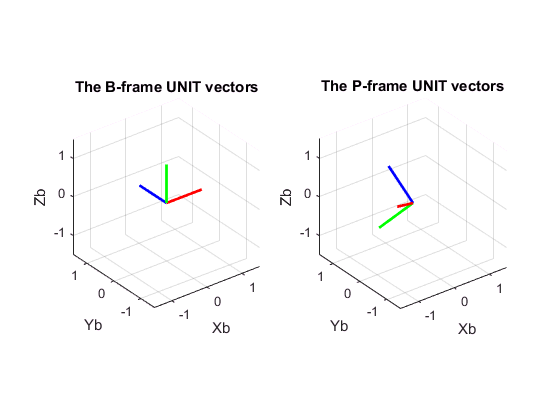

SRC_DATA = load('bh_saved_ellip_cloud.mat');

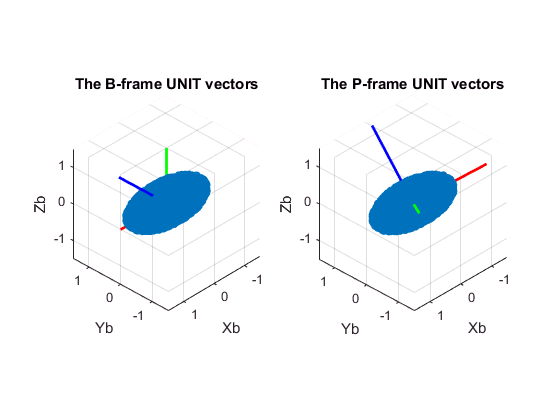

%  SRC_DATA = 
%     new_x_col: [10456x1 double]
%     new_y_col: [10456x1 double]
%     new_z_col: [10456x1 double]

figure;
subplot(1,2,1)
        scatter3(SRC_DATA.new_x_col, SRC_DATA.new_y_col, SRC_DATA.new_z_col); 
            % Plot the B-frame DOUBLE unit vectors 
            bx_u = [2;0;0];
            by_u = [0;2;0];
            bz_u = [0;0;2];
            hold('on');      
        bh_plot_triad( gca, bx_u, by_u, bz_u );   view(-134,-34)
        title('The B-frame UNIT vectors')
subplot(1,2,2);
        scatter3(SRC_DATA.new_x_col, SRC_DATA.new_y_col, SRC_DATA.new_z_col);  
            % express the DOUBLE unit vectors of P into their components in the B-frame 
            b_xi_p = pRb.' * [2;0;0];
            b_yi_p = pRb.' * [0;2;0];
            b_zi_p = pRb.' * [0;0;2];
            hold('on');
        bh_plot_triad( gca, b_xi_p, b_yi_p, b_zi_p );   view(-134,-34)
            title('The P-frame UNIT vectors')                   
